# Embedded Control Systems Degin LAB, MSSE 20-22

# (LQR Based Optimal Design)

## Group No:                   4

## Group Members:        

###                                             Ayesha Ashraf

###                                             Muhammad Qaisar Ali

###                                             Nouman Ali

###                                             Syed Saad Waqar

## Given Open Loop Plant Transfer Function.

## Finding State Space from Given OL-TF

% clear all;  

G = tf(1, [1 3 4])

G =
 
        1
  -------------
  s^2 + 3 s + 4
 
Continuous-time transfer function.



sys_ol= ss(G)

sys_ol =
 
  A = 
       x1  x2
   x1  -3  -2
   x2   2   0
 
  B = 
        u1
   x1  0.5
   x2    0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A= sys_ol.A;
B= sys_ol.B;
C= sys_ol.C;
D= sys_ol.D;

## Open Loop System Responce

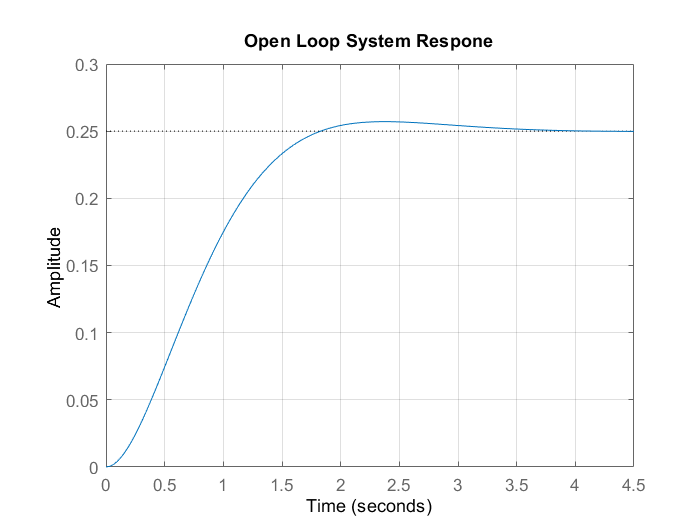

step(sys_ol);
title("Open Loop System Respone");
grid on;

## Inserting Intergator

We can see that the system is stable but have high steady state error, to remove steady state errors, introducing an integrator in System,

Hence the Augumented Matricies are.

A_hat = [A zeros(length(A),1);  % A_hat= |A  0|
         -C 0]                  %        |-C 0|                   

A_hat =     -3    -2     0
     2     0     0
     0    -1     0


 B_hat = [B;                    % B_hat= |B|
          0]                    %        |0|                    

B_hat =     0.5000
         0
         0


## Checking Controlability

M = ctrb(A_hat,B_hat);

rnkM = rank(M);

if (rnkM == length(A_hat))
    disp("The System is controable and hence " + ...
        "state feedback controller can be designed");
else
    disp("The System is un controable and hence " + ...
        "state feedback controller can not be designed");
end

The System is controable and hence state feedback controller can be designed


## Choosing Q and R.

We will be choosing Q and R as Identity and then tweaking its elemnts to makes the responces desied.

As A_hat matrix is 3x3 so Q will be 3x3 symetric matrix as well, also we have single input, u, so R is 1x1, or real number.

Feel free to change diagonal elemets of Q and value of R and observe the output responce.

Q = [1 0 0;
     0 1 0;
     0 0 10]    

Q =      1     0     0
     0     1     0
     0     0    10


R = 0.005      % make it small relative to elements of Q for making responce fast.

R = 0.0050

## Finding Stae Feedback Gain K and Integral Gain Ki.

K_hat = lqr(A_hat, B_hat, Q, R)

K_hat =    15.9255   30.5910  -44.7214


K = K_hat(1,1:length(K_hat)-1)  %K1

K =    15.9255   30.5910


Ki = K_hat(1,length(K_hat))     %K2

Ki = -44.7214

## Implimented in Simulink

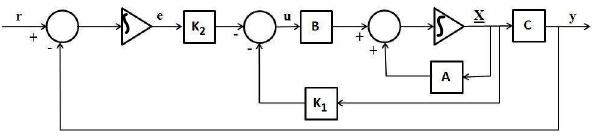

## Closed Loop System Responce from Silumink with Full State Feedback.

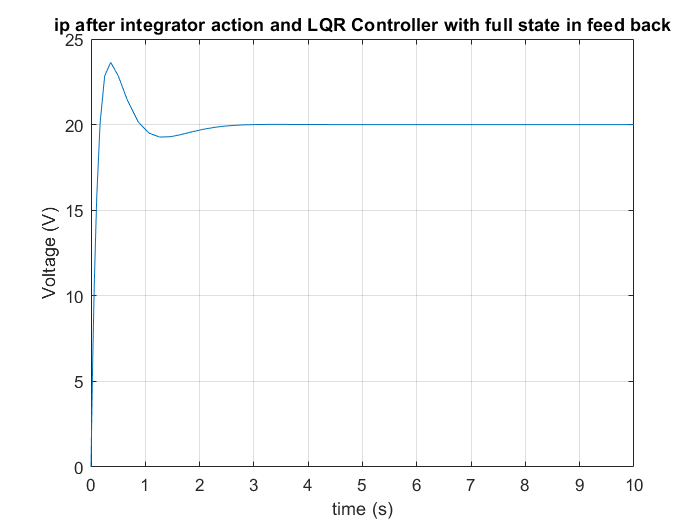

t_final = 10;                         % fed to simulink, 10 secs simulation time.
ref_sig = 5;                          % fed to simulink, you may select any 
                                      % value for ref_sig, 1 is for unit step input.
                                      
out_res_full = sim('LQR_Based_Optimal_Design_Simulink_full_state_based.slx'); % running simulation.

t_full = out_res_full.tout;             % fetched from simulink. full means that variables
u_full = out_res_full.u.signals.values; % are accosciated with controoler which have
y_full = out_res_full.y.signals.values; % full states in feeback.
x1_full  = out_res_full.states.signals.values(:,1);
x2_full  = out_res_full.states.signals.values(:,2);


plot(t_full , u_full);
title("ip after integrator action and LQR Controller with full state in feed back");
xlabel("time (s)");
ylabel("Voltage (V)");
grid on;

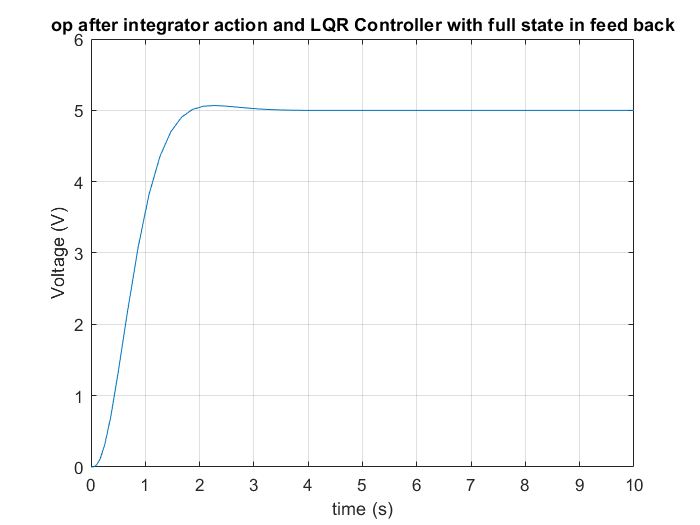


plot(t_full , y_full);
title("op after integrator action and LQR Controller with full state in feed back");
xlabel("time (s)");
ylabel("Voltage (V)");
grid on;

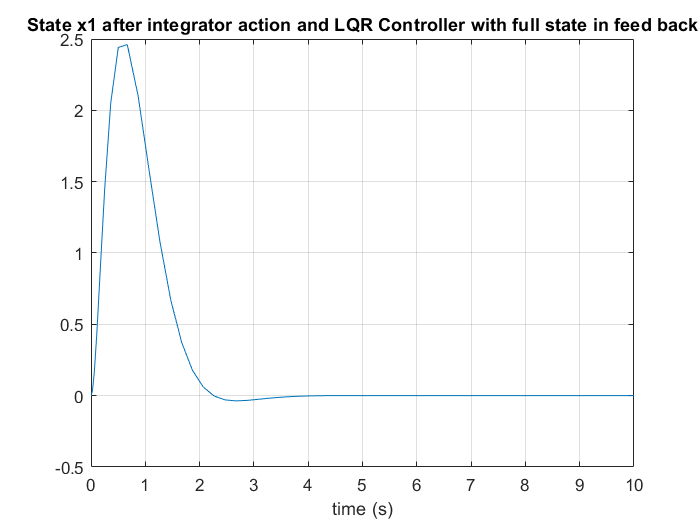


plot(t_full , x1_full);
title("State x1 after integrator action and LQR Controller with full state in feed back");
xlabel("time (s)");
grid on;

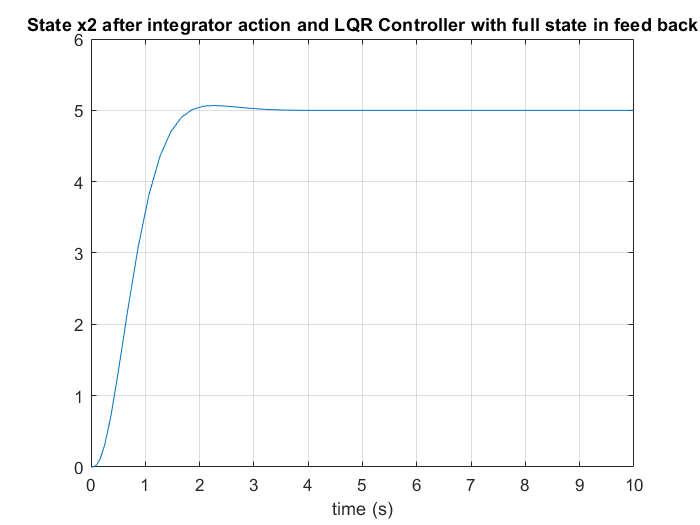


plot(t_full , x2_full);
title("State x2 after integrator action and LQR Controller with full state in feed back");
xlabel("time (s)");
grid on;

#### We can see that input to the plant is less tha 24 volt to track a refrence signal between 0 and 5 volt, hence saturation doesn't occurs if we provide 24v + supply, We can also see that rise and settleing time is

#### less than 4.5 seconds and there is no steady state error, so this is a perfect controller as per our needs.

# Controlling and Optimization Ends Here.

# Wait Wait.....

#### In simulink we fed all states from plant to control law, u=-Kx, but in practical its not easy to provide all states.

#### So either we have to make full  order observer or reduced order observer.As in our case y=x2, there fore state x2 is directly avaible from y.

#### But we can also tune Q, such that the impact of x1 in u= - (k11*x1+k12*x2+ki*xi),  reduces, moreover y dependns on x2, as x1 goes to zero within few seconds, hence only with x2 in feed back we will be able to achive our goal. 

#### Lets do that. 

## Choosing Q and R again 

We choose Q and R again, so x1 (k11) effect may reduce in percentage on over all u, u = k11*x1 + k12*x2 + ki* xi.

Here we made Q(1,1) = 0, so x1 importance/weightage will reduce.

Q_new = [0 0 0;
         0 10 0;
         0 0 30]    

Q_new =      0     0     0
     0    10     0
     0     0    30


R_new = 0.15      % make it small relative to elements of Q for making responce fast.

R_new = 0.1500

## Finding Stae Feedback Gain K and Integral Gain Ki again.

K_hat = lqr(A_hat, B_hat, Q_new, R_new)

K_hat =     5.3464   11.5926  -14.1421


K_new = K_hat(1,2)  % only k12

K_new = 11.5926

Ki_new = K_hat(1,length(K_hat)) 

Ki_new = -14.1421

## Closed Loop System Responce from Silumink with only x2 in control law.

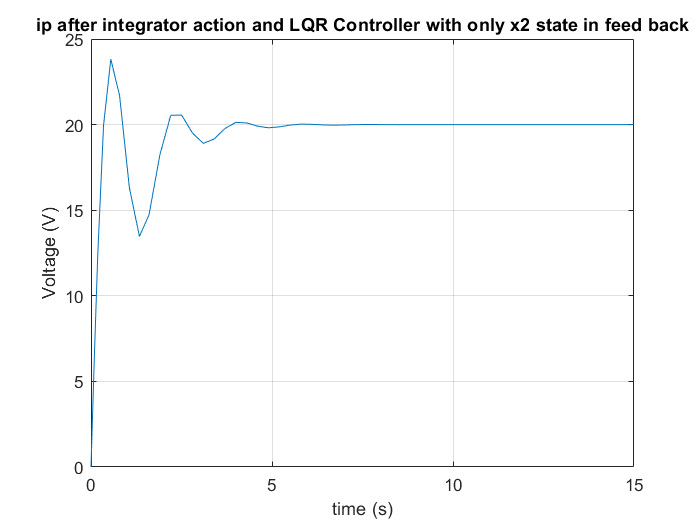

t_final_new = 15;     % fed to simulink, 15 secs simulation time.
ref_sig_new = 5;      % fed to simulink, you may select between 0 and 5 volt.
                      % value for ref_sig, 1 is for unit step input.
                                      
out_res_partial = sim('LQR_Based_Optimal_Design_Simulink_with_1_State.slx'); % running simulation.

t_partial = out_res_partial.tout;             % fetched from simulink. patial means
u_partial = out_res_partial.u.signals.values; % that the variables are accosciated with
y_partial = out_res_partial.y.signals.values; % controoler which have only x2 in state feeback.
x1_partial  = out_res_partial.states.signals.values(:,1);
x2_partial  = out_res_partial.states.signals.values(:,2);


plot(t_partial , u_partial);
title("ip after integrator action and LQR Controller with only x2 state in feed back");
xlabel("time (s)");
ylabel("Voltage (V)");
grid on;

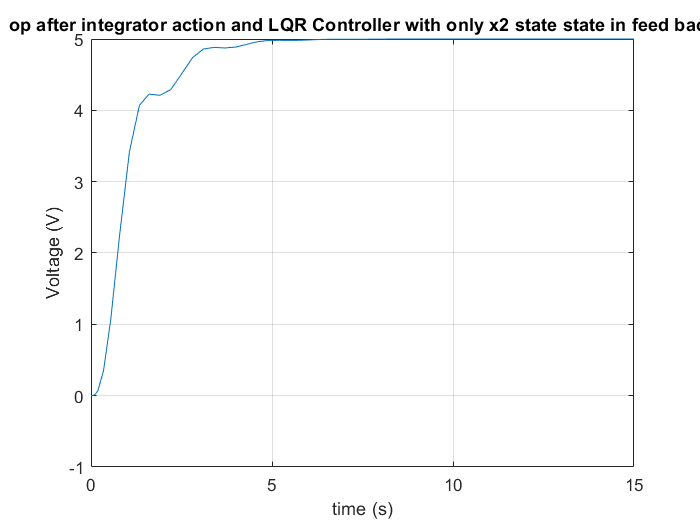


plot(t_partial , y_partial);
title("op after integrator action and LQR Controller with only x2 state state in feed back");
xlabel("time (s)");
ylabel("Voltage (V)");
grid on;

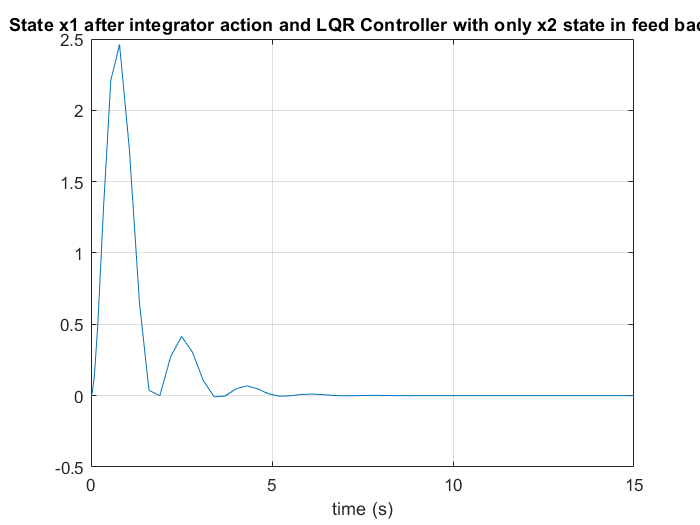


plot(t_partial , x1_partial);
title("State x1 after integrator action and LQR Controller with only x2 state in feed back");
xlabel("time (s)");
grid on;

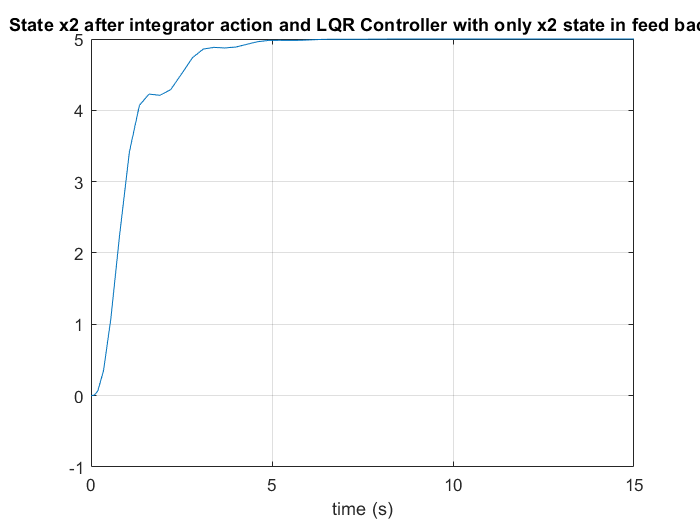


plot(t_partial , x2_partial);
title("State x2 after integrator action and LQR Controller with only x2 state in feed back");
xlabel("time (s)");
grid on;

# Yayy..

#### We can see that input to the plant is less tha 24 volt to track a refrence signal between 0 and 5 volt. So saturation doesn't occurs if we provide 24v + supply. 

#### More over we now have perfect regulation only with feedback law (u=-kx) containing x2 only. x2 can be easily calculated from output, as y=x2 (it can be sen from C matrix). hence we were able to only impliment out controller with only 1 state, x2, in feedback and hence there is no state observer needed. 

#### Moreover settleing time is also acceptable, less than 6 seconds.

# Now Relly the Controlling and Optimization Ends Here.